# **IO145 - DMA Loopback**

This example demonstrates how two analog inputs and outputs present on the IO145 I/O module communicate using DMA (Direct Memory Access). The model is triggered by the IO145's DMA interrupt.

The IO145 is a 16-bit analog module with 8 analog current inputs and 16 single-ended or 8 differential analog high voltage inputs, 8 analog outputs, and 8 digital TTL I/O lines individually configurable as inputs or outputs.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO145 I/O module installed

- Connector cable from the I/O module to the terminal board

- 68-pin terminal board with jumper wires

### Pin Mapping/Connection Diagram/Test Setup

This example outputs a sine wave signal on the analog voltage outputs. The output channels are wired back to the analog input channels, where the voltage is measured and displayed in Simulink.

On the terminal board of the analog I/O module, connect the analog output pins with the analog input pins. The wiring is shown in the table below:

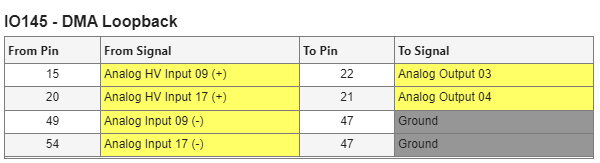

[IO145 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io145_pin_mapping)

## Initialize and Open the Simulink model

This setup calculates a frame-based sinusoidal signal, where the module samples at 5 kHz with a frame size of 5 resulting in a 1 kHz model rate. Alternatively, you can use the  [DSP Sine Wave](https://www.mathworks.com/help/dsp/ref/sinewave.html) block.

 
% Parameters
moduleRate = 5000;                % Module sampling frequency (Hz)
frameSize = 5;                    % Samples per frame
modelRate = frameSize/moduleRate; % Rate the model is triggered
sineFreq = 5;                     % Frequency of sine wave (Hz)
duration = 15;                    % Duration of the signal (seconds)

% Derived parameters
t = 0:1/moduleRate:duration-1/moduleRate;
sineWave = sin(2*pi*sineFreq*t);

% Frame-based organization
numFrames = floor(length(sineWave) / frameSize);
sineFrames = reshape(sineWave(1:numFrames*frameSize), frameSize, numFrames);
frameTimes = (0:numFrames-1) * modelRate;

% Timeseries object
frameBasedSineWave = timeseries(sineFrames', frameTimes);
frameBasedSineWave.Name = 'FrameBasedSineWave';
frameBasedSineWave.DataInfo.Units = 'Amplitude';
frameBasedSineWave.TimeInfo.Units = 'seconds';

% Open Simulink model
modelName = 'sgMdl_IO145_DMALoopback';
open_system(modelName);

### Model Description

The Simulink model features the [IO145 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io145_setup), [IO145 Analog input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io145_analog_input), [IO145 Analog output](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io145_analog_output), and [Interrupt Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_interrupt_setup) blocks. Analog input channels 9 and 17, and output channels 3 and 4 are enabled in the [IO145 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io145_setup) block. Furthermore, the model features a [Interrupt Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_interrupt_setup) block, configured as model trigger. If you wish to reuse the example in a larger Simulink model, consider placing the blocks into a function-triggered subsystem and configuring the Interrupt Setup block accordingly.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10);
tg.stop;

### Check the Results

In the analog input scope you can see the two sine signals sent from analog output channels 3 and 4 to analog input channels 9 and 17 respectively.

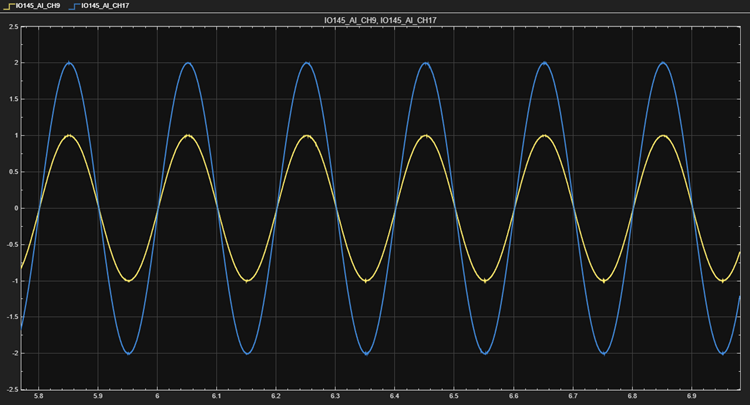

## Additional References

- [IO145 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io145)

- [DSP System Toolbox: Sample- and Frame-Based Concepts](https://mathworks.com/help/dsp/ug/sample-and-frame-based-concepts.html)